clear all; close all;

Correction of Example 2 not using SYMBOLIC COMPUTING, Now, E A L have values !!!

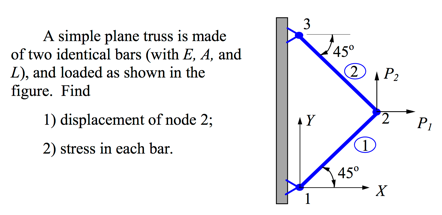

E=20e3 %MPa

E = 20000

A=20*20

A = 400

L=1000 %mm 

L = 1000


alpha=E*A/L

alpha = 8000

k=alpha*[1 -1;-1 1]

k =         8000       -8000
       -8000        8000




%2 orientations 45;135°
%can also use symbolic here
%theta1 = sym([pi/43])
theta1=pi/4;
l1=cos(theta1);
m1=sin(theta1);
theta2=3*pi/4;
l2=cos(theta2);
m2=sin(theta2);

%augmented problem
T_tilde1=[l1 m1;-m1 l1];
T1=zeros(4,4);
T1(1:2,1:2)=T_tilde1;
T1(3:4,3:4)=T_tilde1

T1 =     0.7071    0.7071         0         0
   -0.7071    0.7071         0         0
         0         0    0.7071    0.7071
         0         0   -0.7071    0.7071



T_tilde2=[l2 m2;-m2 l2];
T2=zeros(4,4);
T2(1:2,1:2)=T_tilde2;
T2(3:4,3:4)=T_tilde2

T2 =    -0.7071    0.7071         0         0
   -0.7071   -0.7071         0         0
         0         0   -0.7071    0.7071
         0         0   -0.7071   -0.7071


%syms k_prime
k_prime=(zeros(4,4));
k_prime(1,1)=k(1,1);
k_prime(1,3)=k(1,2);
k_prime(3,1)=k(2,1);
k_prime(3,3)=k(2,2)

k_prime =         8000           0       -8000           0
           0           0           0           0
       -8000           0        8000           0
           0           0           0           0



k1=T1'*k_prime*T1

k1 = 	1.0e+03 *

    4.0000    4.0000   -4.0000   -4.0000
    4.0000    4.0000   -4.0000   -4.0000
   -4.0000   -4.0000    4.0000    4.0000
   -4.0000   -4.0000    4.0000    4.0000


k2=T2'*k_prime*T2

k2 = 	1.0e+03 *

    4.0000   -4.0000   -4.0000    4.0000
   -4.0000    4.0000    4.0000   -4.0000
   -4.0000    4.0000    4.0000   -4.0000
    4.0000   -4.0000   -4.0000    4.0000


%assembly
K=(zeros(6,6));
K(1:4,1:4)=k1(1:4,1:4);
K(3:6,3:6)=k2(1:4,1:4);
K(3:4,3:4)= k1(3:4,3:4)+k2(1:2,1:2)

K = 	1.0e+03 *

    4.0000    4.0000   -4.0000   -4.0000         0         0
    4.0000    4.0000   -4.0000   -4.0000         0         0
   -4.0000   -4.0000    8.0000         0   -4.0000    4.0000
   -4.0000   -4.0000         0    8.0000    4.0000   -4.0000
         0         0   -4.0000    4.0000    4.0000   -4.0000
         0         0    4.0000   -4.0000   -4.0000    4.0000




P1=100 %N

P1 = 100

P2=200 %N

P2 = 200


f=[0 0 P1 P2 0 0]'

f =      0
     0
   100
   200
     0
     0


%full problem
U_full=inv(K)*f

U_full = 	1.0e+14 *

    2.2266
    2.4407
    0.1070
    4.4632
    0.1020
    4.4582


dof_condensed=[3:4];
%condensed
U_condensed=inv(K(dof_condensed,dof_condensed))*f(dof_condensed)

U_condensed =     0.0125
    0.0250



%partionned
%   Special case: ALL imposed displacements are zero 
% (Ub = 0)

freedofs=[3:4];
constraineddofs=[1:2 5:6];
Kaa=K(freedofs,freedofs)

Kaa =         8000           0
           0        8000


Kba=K(constraineddofs,freedofs)

Kba = 	1.0e+03 *

   -4.0000   -4.0000
   -4.0000   -4.0000
   -4.0000    4.0000
    4.0000   -4.0000


fa=f(freedofs)

fa =    100
   200


Ua=inv(Kaa)*fa

Ua =     0.0125
    0.0250


R=Kba*Ua

R =  -150.0000
 -150.0000
   50.0000
  -50.0000


%on x
R(1)+R(3)

ans = -100.0000

% Check reactions wrt external forces 
%on x
if (round(R(1)+R(3))==-P1)
    fprintf('Equilibrium on x axis verified succesfully!\n')
else 
    fprintf('Equilibrium missmatch on x axis. Verify code.\n')
end

Equilibrium on x axis verified succesfully!


%on y
R(2)+R(4)

ans = -200


%on y
if (round(R(2)+R(4))==-P2)
    fprintf('Equilibrium on y axis verified succesfully!\n')
else 
    fprintf('Equilibrium missmatch on x axis. Verify code.\n')
end

Equilibrium on y axis verified succesfully!



B=[-1/L 1/L];
Sigma1=E*B*[T1(1,:);T1(3,:)]*[ 0;0; Ua];

fprintf(('S1 = %5.3f MPa\n'),Sigma1); %Print stress in element 1

S1 = 0.530 MPa


Sigma2=E*B*[T2(1,:);T2(3,:)]*[ Ua ;0; 0];

fprintf(('S2 = %5.3f MPa\n'),Sigma2); %Print stress in element 1

S2 = -0.177 MPa


## Optional: Opt. section area

%Reserve Factor
sigma = 250; % Yield strength, MPa
RF = sigma/max(abs(Sigma1),abs(Sigma2));

fprintf('Initial RF: %g \n', RF);

Initial RF: 471.405 



%% Optimization

%stresses are inversely proportional to the section; therefore, the RF is
%directly proportional to the section
Aopt = A/RF;
stress1opt = Sigma1*A/Aopt;
stress2opt = Sigma2*A/Aopt;
RFopt = sigma/max(abs(stress1opt),abs(stress2opt));

fprintf('The optimal section is : %g mm^2\n', Aopt);

The optimal section is : 0.848528 mm^2


fprintf('The RF obtained with the optimization is : %g\n', RFopt);

The RF obtained with the optimization is : 1


`Since there is no margin and with very small loads:`

`the optimal section area is very small. `

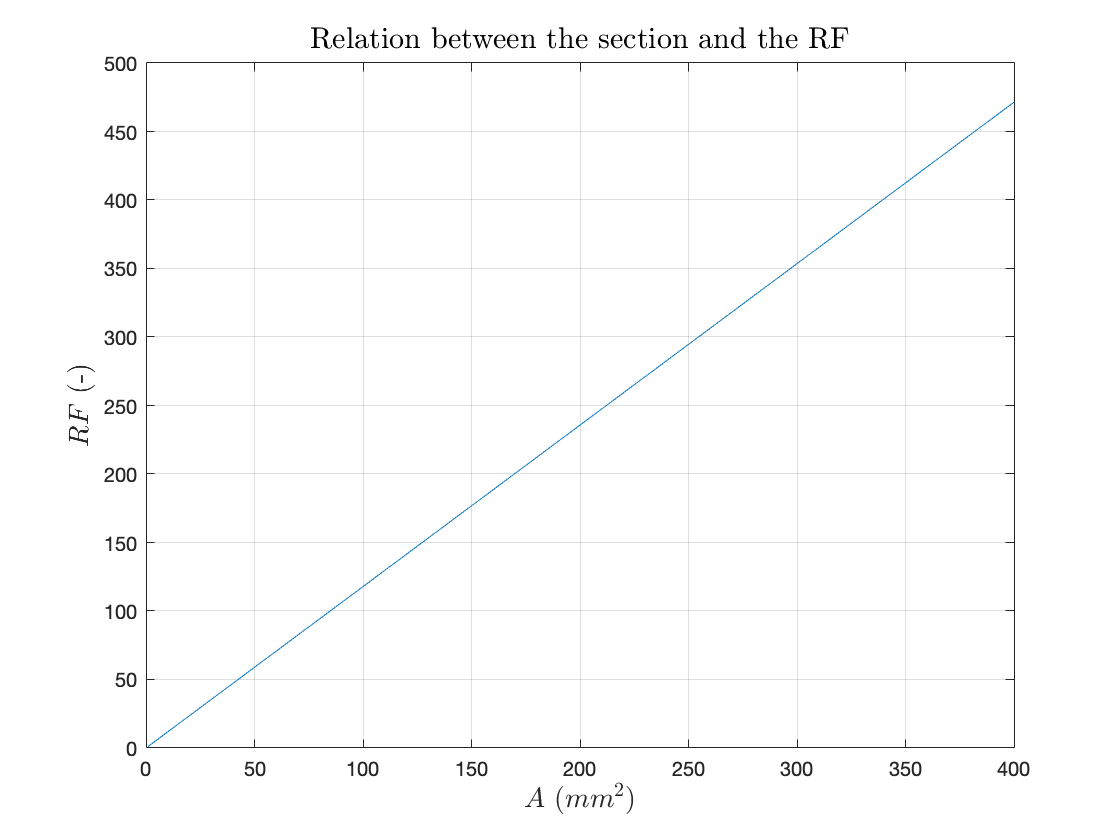

%the proportionality relation can be verified with the next plot
Areas = linspace(A,Aopt,100);
stress1list = Sigma1*A./Areas;
stress2list = Sigma2*A./Areas;
RFlist = zeros(size(Areas));

for i=1:length(Areas)
    RFlist(i) = sigma/max(abs(stress1list(i)),abs(stress2list(i)));
end

figure
plot1=plot(Areas,RFlist); hold on;
title('Relation between the section and the RF','Interpreter','latex','FontSize',15)
xlabel('$A$ ($mm^{2}$)','Interpreter','latex','FontSize',14)
ylabel('$RF$ (-)','Interpreter','latex','FontSize',14)
grid on

ax1 = ancestor(plot1, 'axes');
yrule1 = ax1.YAxis;
xrule1 = ax1.XAxis;

% % ------ Find optimal section area for RF=1
% RF = 1;
% Sy = 250; % Yield strength, MPa
% Sw = Sy/RF % Working strength, MPa
% A1 = sqrt(2)/2/Sw*(P1+P2); % Area in element 1, mm^2
% A2 = sqrt(2)/2/Sw*(P1-P2); % Area in element 2, mm^2 
% Aopt = max(A1,A2); % Optimal area, mm^2
% fprintf(('With RF = %5.2f, Aopt = %5.3f mm^2\n'),RF,Aopt); %Print optimal area